load("data_np4nc4.mat")
load("data_np10nc4.mat")
load("data_np20nc4.mat")
load("data_np20nc10.mat")
load("data_np20nc20.mat")

load("data_np20nc20_dist.mat")
load("data_np20nc10_dist.mat")
load("data_np20nc4_dist.mat")
load("data_np10nc4_dist.mat")
load("data_np4nc4_dist.mat")

load("data_np20nc20_kiln.mat")
load("data_np20nc20_cyc.mat")
load("data_np20nc10_kiln.mat")
load("data_np20nc10_cyc.mat")
load("data_np20nc4_kiln.mat")
load("data_np20nc4_cyc.mat")
load("data_np10nc4_kiln.mat")
load("data_np10nc4_cyc.mat")
load("data_np4nc4_kiln.mat")
load("data_np4nc4_cyc.mat")

load("data_np20nc20_cyc_dist.mat")
load("data_np20nc10_cyc_dist.mat")
load("data_np20nc4_cyc_dist.mat")
load("data_np10nc4_cyc_dist.mat")
load("data_np4nc4_cyc_dist.mat")

load("data_np20nc20_kiln_dist.mat")
load("data_np20nc10_kiln_dist.mat")
load("data_np20nc4_kiln_dist.mat")
load("data_np10nc4_kiln_dist.mat")
load("data_np4nc4_kiln_dist.mat")

load("data_np12nc4.mat")
load("data_np12nc4_dist.mat")

load("data_np12nc4_cyc.mat")
load("data_np12nc4_cyc_dist.mat")

load("data_np12nc4_kiln.mat")
load("data_np12nc4_kiln_dist.mat")

load("data_simulation.mat")
load("data_simulation_dist.mat")

## Print Ulang

% Set default font size for axes
set(0, 'DefaultAxesFontSize', 12);

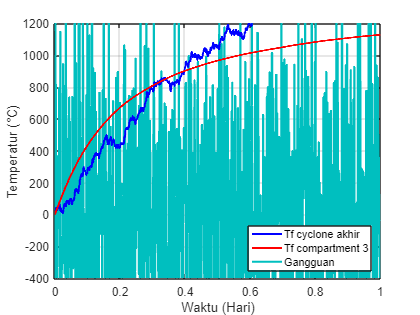

figure(2)

h6 = plot(data_simulation_dist.time, data_simulation_dist.Data(:,3), 'Color',[0, 0.75, 0.75], 'LineWidth',2, 'DisplayName', "Gangguan");
hold on;
h1 = plot(data_simulation_dist.time,data_simulation_dist.Data(:,1), 'Color','blue', 'LineWidth',2, 'DisplayName',"Tf cyclone akhir");

h2 = plot(data_simulation_dist.time, data_simulation_dist.Data(:,2), 'Color','red', 'LineWidth',2, 'DisplayName',"Tf compartment 3");
%h4 = yline(850, '--', 'LineWidth', 2, 'Color', [0.75, 0.75, 0], 'DisplayName', 'Setpoint Y1');
%h5 = yline(1450, '--', 'LineWidth', 2, 'Color', [0.85, 0.33, 0.1], 'DisplayName', 'Setpoint Y2');

xlim([data_simulation_dist.time(1), data_simulation_dist.time(end)])
ylim([-400, 1200])
legend([h1, h2, h6], 'Location', 'southeast')

ylabel("Temperatur (°C)")
xlabel("Waktu (Hari)")
grid on
hold off

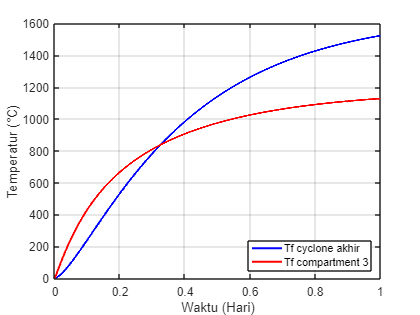

figure(2)

h1 = plot(data_simulation.time,data_simulation.Data(:,1), 'Color','blue', 'LineWidth',2, 'DisplayName',"Tf cyclone akhir");
hold on;
h2 = plot(data_simulation.time, data_simulation.Data(:,2), 'Color','red', 'LineWidth',2, 'DisplayName',"Tf compartment 3");
%h4 = yline(850, '--', 'LineWidth', 2, 'Color', [0.75, 0.75, 0], 'DisplayName', 'Setpoint Y1');
%h5 = yline(1450, '--', 'LineWidth', 2, 'Color', [0.85, 0.33, 0.1], 'DisplayName', 'Setpoint Y2');
%h6 = plot(data_np10nc4_dist.time, data_np20nc4_dist.Data(:,3), 'Color',[0, 0.75, 0.75], 'LineWidth',2, 'DisplayName', "Gangguan");
xlim([data_simulation.time(1), data_simulation.time(end)])
ylim([min(data_simulation.Data(:, 1)), 1600])
legend([h1, h2], 'Location', 'southeast')

ylabel("Temperatur (°C)")
xlabel("Waktu (Hari)")
grid on
hold off

### **Open Loop **

figure(2)

h1 = plot(data_simulation.time,data_simulation.Data(:,1), 'Color','blue', 'LineWidth',2, 'DisplayName',"Tf cyclone akhir");
hold on;
h2 = plot(data_simulation.time, data_simulation.Data(:,2), 'Color','red', 'LineWidth',2, 'DisplayName',"Tf compartment 3");
%h4 = yline(850, '--', 'LineWidth', 2, 'Color', [0.75, 0.75, 0], 'DisplayName', 'Setpoint Y1');
%h5 = yline(1450, '--', 'LineWidth', 2, 'Color', [0.85, 0.33, 0.1], 'DisplayName', 'Setpoint Y2');
%h6 = plot(data_np10nc4_dist.time, data_np20nc4_dist.Data(:,3), 'Color',[0, 0.75, 0.75], 'LineWidth',2, 'DisplayName', "Gangguan");
xlim([data_simulation.time(1), data_simulation.time(end)])
ylim([min(data_simulation.Data(:, 1)), 1600])
legend([h1, h2], 'Location', 'southeast')

ylabel("Temperatur (°C)")
xlabel("Waktu (Hari)")
grid on
hold off

Open Loop Dengan Gangguan

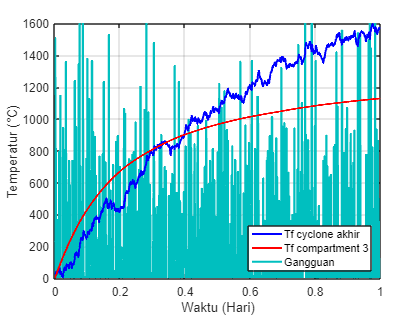

figure(2)

h6 = plot(data_simulation_dist.time, data_simulation_dist.Data(:,3), 'Color',[0, 0.75, 0.75], 'LineWidth',2, 'DisplayName', "Gangguan");
hold on;
h1 = plot(data_simulation_dist.time,data_simulation_dist.Data(:,1), 'Color','blue', 'LineWidth',2, 'DisplayName',"Tf cyclone akhir");

h2 = plot(data_simulation_dist.time, data_simulation_dist.Data(:,2), 'Color','red', 'LineWidth',2, 'DisplayName',"Tf compartment 3");
%h4 = yline(850, '--', 'LineWidth', 2, 'Color', [0.75, 0.75, 0], 'DisplayName', 'Setpoint Y1');
%h5 = yline(1450, '--', 'LineWidth', 2, 'Color', [0.85, 0.33, 0.1], 'DisplayName', 'Setpoint Y2');

xlim([data_simulation_dist.time(1), data_simulation_dist.time(end)])
ylim([min(data_simulation_dist.Data(:, 1)), 1600])
legend([h1, h2, h6], 'Location', 'southeast')

ylabel("Temperatur (°C)")
xlabel("Waktu (Hari)")
grid on
hold off

### Single Test MPC Np 12 Nc 4

**MIMO MPC**

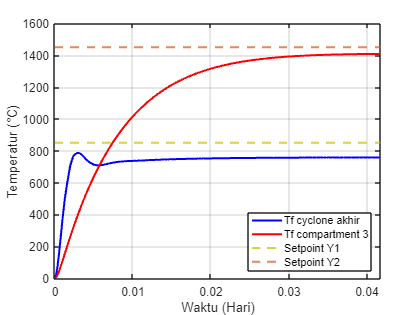

figure(2)

h1 = plot(data_np12nc4.time,data_np12nc4.Data(:,1), 'Color','blue', 'LineWidth',2, 'DisplayName',"Tf cyclone akhir");
hold on;
h2 = plot(data_np12nc4.time, data_np12nc4.Data(:,2), 'Color','red', 'LineWidth',2, 'DisplayName',"Tf compartment 3");
h4 = yline(850, '--', 'LineWidth', 2, 'Color', [0.75, 0.75, 0], 'DisplayName', 'Setpoint Y1');
h5 = yline(1450, '--', 'LineWidth', 2, 'Color', [0.85, 0.33, 0.1], 'DisplayName', 'Setpoint Y2');
%h6 = plot(data_np10nc4_dist.time, data_np20nc4_dist.Data(:,3), 'Color',[0, 0.75, 0.75], 'LineWidth',2, 'DisplayName', "Gangguan");
xlim([data_np10nc4_dist.time(1), data_np10nc4_dist.time(end)])
ylim([min(data_np4nc4_dist.Data(:, 1)), 1600])
legend([h1, h2, h4, h5], 'Location', 'southeast')

ylabel("Temperatur (°C)")
xlabel("Waktu (Hari)")
grid on
hold off

**MIMO MPC dengan Gangguan**

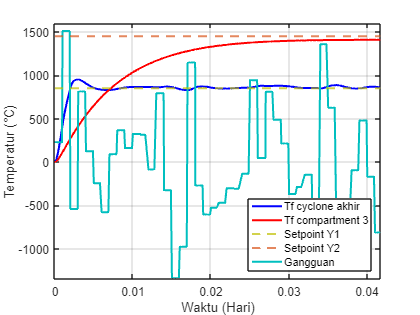

figure(2)

h1 = plot(data_np12nc4_dist.time,data_np12nc4_dist.Data(:,1), 'Color','blue', 'LineWidth',2, 'DisplayName',"Tf cyclone akhir");
hold on;
h2 = plot(data_np12nc4_dist.time, data_np12nc4_dist.Data(:,2), 'Color','red', 'LineWidth',2, 'DisplayName',"Tf compartment 3");
h4 = yline(850, '--', 'LineWidth', 2, 'Color', [0.75, 0.75, 0], 'DisplayName', 'Setpoint Y1');
h5 = yline(1450, '--', 'LineWidth', 2, 'Color', [0.85, 0.33, 0.1], 'DisplayName', 'Setpoint Y2');
h6 = plot(data_np12nc4_dist.time, data_np12nc4_dist.Data(:,3), 'Color',[0, 0.75, 0.75], 'LineWidth',2, 'DisplayName', "Gangguan");
xlim([data_np10nc4_dist.time(1), data_np10nc4_dist.time(end)])
ylim([min(data_np12nc4_dist.Data(:, 3)), 1600])
legend([h1, h2, h4, h5, h6], 'Location', 'southeast')

ylabel("Temperatur (°C)")
xlabel("Waktu (Hari)")
grid on
hold off

### **SISO MPC **

**cyclone tanpa gangguan**

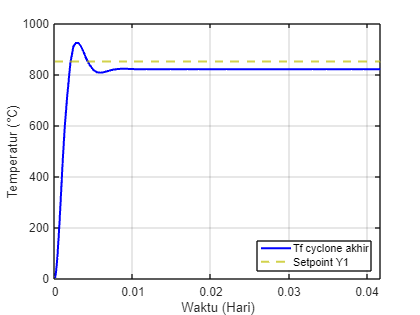

figure(2)

h1 = plot(data_np12nc4.time,data_np12nc4_cyc.Data(:,1), 'Color','blue', 'LineWidth',2, 'DisplayName',"Tf cyclone akhir");
hold on;
%h2 = plot(data_np12nc4.time, data_np12nc4.Data(:,2), 'Color','red', 'LineWidth',2, 'DisplayName',"Tf compartment 3");
h4 = yline(850, '--', 'LineWidth', 2, 'Color', [0.75, 0.75, 0], 'DisplayName', 'Setpoint Y1');
%h5 = yline(1450, '--', 'LineWidth', 2, 'Color', [0.85, 0.33, 0.1], 'DisplayName', 'Setpoint Y2');
%h6 = plot(data_np10nc4_dist.time, data_np20nc4_dist.Data(:,3), 'Color',[0, 0.75, 0.75], 'LineWidth',2, 'DisplayName', "Gangguan");
xlim([data_np10nc4_dist.time(1), data_np10nc4_dist.time(end)])
ylim([min(data_np4nc4_cyc.Data(:, 1)), 1000])
legend([h1, h4], 'Location', 'southeast')

ylabel("Temperatur (°C)")
xlabel("Waktu (Hari)")
grid on
hold off

**cyclone dengan gangguan**

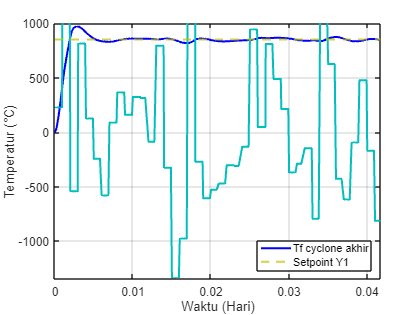

figure(2)

h1 = plot(data_np12nc4_cyc_dist.time,data_np12nc4_cyc_dist.Data(:,1), 'Color','blue', 'LineWidth',2, 'DisplayName',"Tf cyclone akhir");
hold on;
%h2 = plot(data_np12nc4.time, data_np12nc4.Data(:,2), 'Color','red', 'LineWidth',2, 'DisplayName',"Tf compartment 3");
h4 = yline(850, '--', 'LineWidth', 2, 'Color', [0.75, 0.75, 0], 'DisplayName', 'Setpoint Y1');
%h5 = yline(1450, '--', 'LineWidth', 2, 'Color', [0.85, 0.33, 0.1], 'DisplayName', 'Setpoint Y2');
h6 = plot(data_np12nc4_cyc_dist.time, data_np12nc4_cyc_dist.Data(:,2), 'Color',[0, 0.75, 0.75], 'LineWidth',2, 'DisplayName', "Gangguan");
xlim([data_np10nc4_dist.time(1), data_np10nc4_dist.time(end)])
ylim([min(data_np4nc4_cyc_dist.Data(:, 2)), 1000])
legend([h1, h4], 'Location', 'southeast')

ylabel("Temperatur (°C)")
xlabel("Waktu (Hari)")
grid on
hold off

**rotary kiln tanpa gangguan**

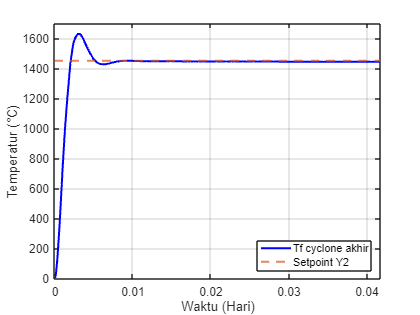

figure(2)

h1 = plot(data_np12nc4.time,data_np12nc4_kiln.Data(:,1), 'Color','blue', 'LineWidth',2, 'DisplayName',"Tf cyclone akhir");
hold on;
%h2 = plot(data_np12nc4.time, data_np12nc4.Data(:,2), 'Color','red', 'LineWidth',2, 'DisplayName',"Tf compartment 3");
%h4 = yline(850, '--', 'LineWidth', 2, 'Color', [0.75, 0.75, 0], 'DisplayName', 'Setpoint Y1');
h5 = yline(1450, '--', 'LineWidth', 2, 'Color', [0.85, 0.33, 0.1], 'DisplayName', 'Setpoint Y2');
%h6 = plot(data_np10nc4_dist.time, data_np20nc4_dist.Data(:,3), 'Color',[0, 0.75, 0.75], 'LineWidth',2, 'DisplayName', "Gangguan");
xlim([data_np10nc4_dist.time(1), data_np10nc4_dist.time(end)])
ylim([min(data_np4nc4_cyc.Data(:, 1)), 1700])
legend([h1, h5], 'Location', 'southeast')

ylabel("Temperatur (°C)")
xlabel("Waktu (Hari)")
grid on
hold off

**rotary kiln dengan gangguan**

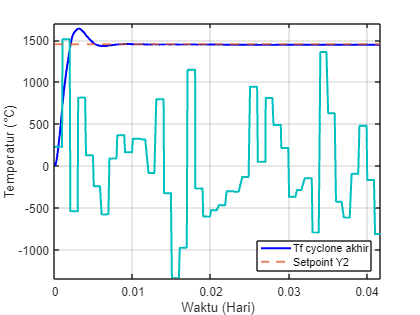

figure(2)

h1 = plot(data_np12nc4_cyc_dist.time,data_np12nc4_kiln_dist.Data(:,1), 'Color','blue', 'LineWidth',2, 'DisplayName',"Tf cyclone akhir");
hold on;
%h2 = plot(data_np12nc4.time, data_np12nc4.Data(:,2), 'Color','red', 'LineWidth',2, 'DisplayName',"Tf compartment 3");
%h4 = yline(850, '--', 'LineWidth', 2, 'Color', [0.75, 0.75, 0], 'DisplayName', 'Setpoint Y1');
h5 = yline(1450, '--', 'LineWidth', 2, 'Color', [0.85, 0.33, 0.1], 'DisplayName', 'Setpoint Y2');
h6 = plot(data_np12nc4_cyc_dist.time, data_np12nc4_cyc_dist.Data(:,2), 'Color',[0, 0.75, 0.75], 'LineWidth',2, 'DisplayName', "Gangguan");
xlim([data_np10nc4_dist.time(1), data_np10nc4_dist.time(end)])
ylim([min(data_np4nc4_cyc_dist.Data(:, 2)), 1700])
legend([h1, h5], 'Location', 'southeast')

ylabel("Temperatur (°C)")
xlabel("Waktu (Hari)")
grid on
hold off

**MIMO MPC tanpa gangguan**

**variasi Np**

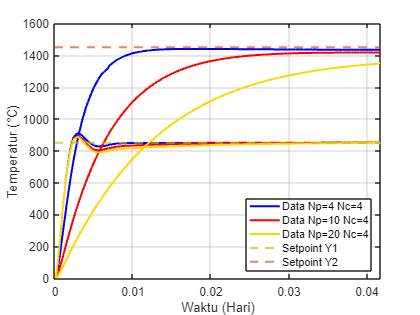

figure(2)
plot(data_np10nc4.time,data_np4nc4.Data(:,[1, 2]), 'Color','blue', 'LineWidth',2)
hold on;
h1 = plot(data_np10nc4.time,data_np4nc4.Data(:,1), 'Color','blue', 'LineWidth',2, 'DisplayName',"Data Np=4 Nc=4");
plot(data_np10nc4.time, data_np10nc4.Data(:,[1, 2]), 'Color','red', 'LineWidth',2)
h2 = plot(data_np10nc4.time, data_np10nc4.Data(:,1), 'Color','red', 'LineWidth',2, 'DisplayName',"Data Np=10 Nc=4");
plot(data_np10nc4.time, data_np20nc4.Data(:,[1, 2]), 'Color',[1, 0.84, 0], 'LineWidth',2)
h3 = plot(data_np10nc4.time, data_np20nc4.Data(:,1), 'Color',[1, 0.84, 0], 'LineWidth',2, 'DisplayName', "Data Np=20 Nc=4");
h4 = yline(850, '--', 'LineWidth', 2, 'Color', [0.75, 0.75, 0], 'DisplayName', 'Setpoint Y1');
h5 = yline(1450, '--', 'LineWidth', 2, 'Color', [0.85, 0.33, 0.1], 'DisplayName', 'Setpoint Y2');
%h6 = plot(data_np10nc4_dist.time, data_np20nc4_dist.Data(:,3), 'Color',[0, 0.75, 0.75], 'LineWidth',2, 'DisplayName', "Gangguan");
xlim([data_np10nc4_dist.time(1), data_np10nc4_dist.time(end)])
ylim([min(data_np4nc4_dist.Data(:, 1)), 1600])
legend([h1, h2, h3, h4, h5], 'Location', 'southeast')

ylabel("Temperatur (°C)")
xlabel("Waktu (Hari)")
grid on
hold off

**variasi Nc**

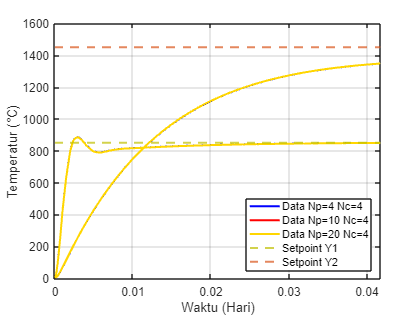

figure(2)
plot(data_np10nc4.time,data_np20nc4.Data(:,[1, 2]), 'Color','blue', 'LineWidth',2)
hold on;
h1 = plot(data_np10nc4.time,data_np20nc4.Data(:,1), 'Color','blue', 'LineWidth',2, 'DisplayName',"Data Np=4 Nc=4");
plot(data_np10nc4.time, data_np20nc10.Data(:,[1, 2]), 'Color','red', 'LineWidth',2)
h2 = plot(data_np10nc4.time, data_np20nc10.Data(:,1), 'Color','red', 'LineWidth',2, 'DisplayName',"Data Np=10 Nc=4");
plot(data_np10nc4.time, data_np20nc20.Data(:,[1, 2]), 'Color',[1, 0.84, 0], 'LineWidth',2)
h3 = plot(data_np10nc4.time, data_np20nc20.Data(:,1), 'Color',[1, 0.84, 0], 'LineWidth',2, 'DisplayName', "Data Np=20 Nc=4");
h4 = yline(850, '--', 'LineWidth', 2, 'Color', [0.75, 0.75, 0], 'DisplayName', 'Setpoint Y1');
h5 = yline(1450, '--', 'LineWidth', 2, 'Color', [0.85, 0.33, 0.1], 'DisplayName', 'Setpoint Y2');
%h6 = plot(data_np10nc4_dist.time, data_np20nc4_dist.Data(:,3), 'Color',[0, 0.75, 0.75], 'LineWidth',2, 'DisplayName', "Gangguan");
xlim([data_np10nc4_dist.time(1), data_np10nc4_dist.time(end)])
ylim([min(data_np4nc4_dist.Data(:, 1)), 1600])
legend([h1, h2, h3, h4, h5], 'Location', 'southeast')

ylabel("Temperatur (°C)")
xlabel("Waktu (Hari)")
grid on
hold off

**MIMO MPC dengan gangguan**

**variasi Np**

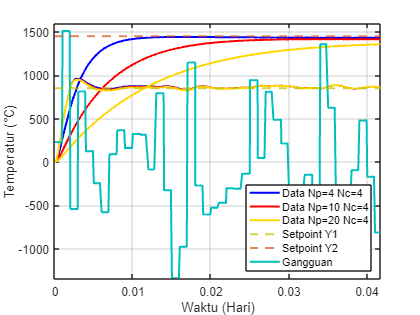

figure(2)
plot(data_np4nc4_dist.time,data_np4nc4_dist.Data(:,[1, 2]), 'Color','blue', 'LineWidth',2)
hold on;
h1 = plot(data_np4nc4_dist.time,data_np4nc4_dist.Data(:,1), 'Color','blue', 'LineWidth',2, 'DisplayName',"Data Np=4 Nc=4");
plot(data_np10nc4_dist.time, data_np10nc4_dist.Data(:,[1, 2]), 'Color','red', 'LineWidth',2)
h2 = plot(data_np10nc4_dist.time, data_np10nc4_dist.Data(:,1), 'Color','red', 'LineWidth',2, 'DisplayName',"Data Np=10 Nc=4");
plot(data_np20nc4_dist.time, data_np20nc4_dist.Data(:,[1, 2]), 'Color',[1, 0.84, 0], 'LineWidth',2)
h3 = plot(data_np20nc4_dist.time, data_np20nc4_dist.Data(:,1), 'Color',[1, 0.84, 0], 'LineWidth',2, 'DisplayName', "Data Np=20 Nc=4");
h4 = yline(850, '--', 'LineWidth', 2, 'Color', [0.75, 0.75, 0], 'DisplayName', 'Setpoint Y1');
h5 = yline(1450, '--', 'LineWidth', 2, 'Color', [0.85, 0.33, 0.1], 'DisplayName', 'Setpoint Y2');
h6 = plot(data_np4nc4_dist.time, data_np4nc4_dist.Data(:,3), 'Color',[0, 0.75, 0.75], 'LineWidth',2, 'DisplayName', "Gangguan");
xlim([data_np4nc4_dist.time(1), data_np4nc4_dist.time(end)])
ylim([min(data_np4nc4_dist.Data(:, 3)), 1600])
legend([h1, h2, h3, h4, h5, h6], 'Location', 'southeast')

ylabel("Temperatur (°C)")
xlabel("Waktu (Hari)")
grid on
hold off

**variasi Nc**

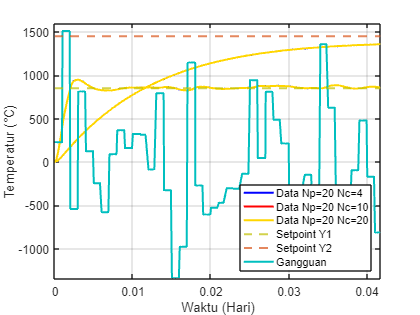

figure(2)
plot(data_np20nc4_dist.time,data_np20nc4_dist.Data(:,[1, 2]), 'Color','blue', 'LineWidth',2)
hold on;
h1 = plot(data_np20nc4_dist.time,data_np20nc4_dist.Data(:,1), 'Color','blue', 'LineWidth',2, 'DisplayName',"Data Np=20 Nc=4");
plot(data_np20nc10_dist.time, data_np20nc10_dist.Data(:,[1, 2]), 'Color','red', 'LineWidth',2)
h2 = plot(data_np20nc10_dist.time, data_np20nc10_dist.Data(:,1), 'Color','red', 'LineWidth',2, 'DisplayName',"Data Np=20 Nc=10");
plot(data_np20nc20_dist.time, data_np20nc20_dist.Data(:,[1, 2]), 'Color',[1, 0.84, 0], 'LineWidth',2)
h3 = plot(data_np20nc20_dist.time, data_np20nc20_dist.Data(:,1), 'Color',[1, 0.84, 0], 'LineWidth',2, 'DisplayName', "Data Np=20 Nc=20");
h4 = yline(850, '--', 'LineWidth', 2, 'Color', [0.75, 0.75, 0], 'DisplayName', 'Setpoint Y1');
h5 = yline(1450, '--', 'LineWidth', 2, 'Color', [0.85, 0.33, 0.1], 'DisplayName', 'Setpoint Y2');
h6 = plot(data_np20nc4_dist.time, data_np20nc4_dist.Data(:,3), 'Color',[0, 0.75, 0.75], 'LineWidth',2, 'DisplayName', "Gangguan");
xlim([data_np20nc4_dist.time(1), data_np20nc4_dist.time(end)])
ylim([min(data_np20nc4_dist.Data(:, 3)), 1600])
legend([h1, h2, h3, h4, h5, h6], 'Location', 'southeast')

ylabel("Temperatur (°C)")
xlabel("Waktu (Hari)")
grid on
hold off

## **SISO MPC**

### **Cyclone Tanpa Gangguan**

**Variasi Np**

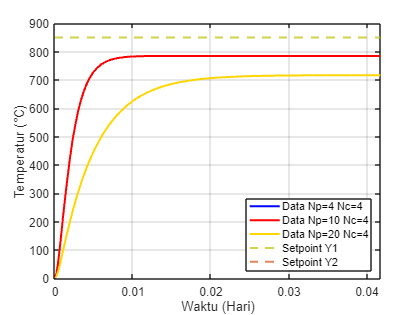

figure(2)
h1 = plot(data_np10nc4_cyc.time,data_np4nc4_cyc.Data(:,1), 'Color','blue', 'LineWidth',2, 'DisplayName',"Data Np=4 Nc=4");
hold on
h2 = plot(data_np10nc4_cyc.time, data_np10nc4_cyc.Data(:,1), 'Color','red', 'LineWidth',2, 'DisplayName',"Data Np=10 Nc=4");
h3 = plot(data_np10nc4_cyc.time, data_np20nc4_cyc.Data(:,1), 'Color',[1, 0.84, 0], 'LineWidth',2, 'DisplayName', "Data Np=20 Nc=4");
h4 = yline(850, '--', 'LineWidth', 2, 'Color', [0.75, 0.75, 0], 'DisplayName', 'Setpoint Y1');
h5 = yline(1450, '--', 'LineWidth', 2, 'Color', [0.85, 0.33, 0.1], 'DisplayName', 'Setpoint Y2');
%h6 = plot(data_np10nc4_dist.time, data_np20nc4_dist.Data(:,3), 'Color',[0, 0.75, 0.75], 'LineWidth',2, 'DisplayName', "Gangguan");
xlim([data_np10nc4_dist.time(1), data_np10nc4_dist.time(end)])
ylim([min(data_np4nc4_dist.Data(:, 1)), 900])
legend([h1, h2, h3, h4, h5], 'Location', 'southeast')

ylabel("Temperatur (°C)")
xlabel("Waktu (Hari)")
grid on
hold off

**Variasi Nc**

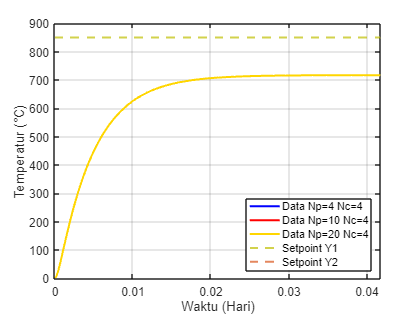

figure(2)
h1 = plot(data_np10nc4_cyc.time,data_np20nc4_cyc.Data(:,1), 'Color','blue', 'LineWidth',2, 'DisplayName',"Data Np=4 Nc=4");
hold on
h2 = plot(data_np10nc4_cyc.time, data_np20nc10_cyc.Data(:,1), 'Color','red', 'LineWidth',2, 'DisplayName',"Data Np=10 Nc=4");
h3 = plot(data_np10nc4_cyc.time, data_np20nc20_cyc.Data(:,1), 'Color',[1, 0.84, 0], 'LineWidth',2, 'DisplayName', "Data Np=20 Nc=4");
h4 = yline(850, '--', 'LineWidth', 2, 'Color', [0.75, 0.75, 0], 'DisplayName', 'Setpoint Y1');
h5 = yline(1450, '--', 'LineWidth', 2, 'Color', [0.85, 0.33, 0.1], 'DisplayName', 'Setpoint Y2');
%h6 = plot(data_np10nc4_dist.time, data_np20nc4_dist.Data(:,3), 'Color',[0, 0.75, 0.75], 'LineWidth',2, 'DisplayName', "Gangguan");
xlim([data_np10nc4_dist.time(1), data_np10nc4_dist.time(end)])
ylim([min(data_np4nc4_dist.Data(:, 1)), 900])
legend([h1, h2, h3, h4, h5], 'Location', 'southeast')

ylabel("Temperatur (°C)")
xlabel("Waktu (Hari)")
grid on
hold off

### **Cyclone Dengan Gangguan**

**Variasi Np**

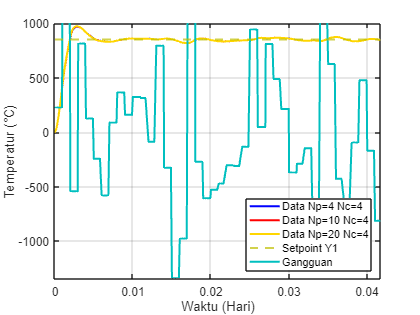

figure(2)
h1 = plot(data_np4nc4_cyc_dist.time,data_np4nc4_cyc_dist.Data(:,1), 'Color','blue', 'LineWidth',2, 'DisplayName',"Data Np=4 Nc=4");
hold on
h2 = plot(data_np10nc4_cyc_dist.time, data_np10nc4_cyc_dist.Data(:,1), 'Color','red', 'LineWidth',2, 'DisplayName',"Data Np=10 Nc=4");
h3 = plot(data_np20nc4_cyc_dist.time, data_np20nc4_cyc_dist.Data(:,1), 'Color',[1, 0.84, 0], 'LineWidth',2, 'DisplayName', "Data Np=20 Nc=4");
h4 = yline(850, '--', 'LineWidth', 2, 'Color', [0.75, 0.75, 0], 'DisplayName', 'Setpoint Y1');
h5 = yline(1450, '--', 'LineWidth', 2, 'Color', [0.85, 0.33, 0.1], 'DisplayName', 'Setpoint Y2');
h6 = plot(data_np20nc4_cyc_dist.time, data_np20nc4_cyc_dist.Data(:,2), 'Color',[0, 0.75, 0.75], 'LineWidth',2, 'DisplayName', "Gangguan");
xlim([data_np10nc4_dist.time(1), data_np10nc4_dist.time(end)])
ylim([min(data_np4nc4_cyc_dist.Data(:, 2)), 1000])
legend([h1, h2, h3, h4, h6], 'Location', 'southeast')

ylabel("Temperatur (°C)")
xlabel("Waktu (Hari)")
grid on
hold off

**Variasi Nc**

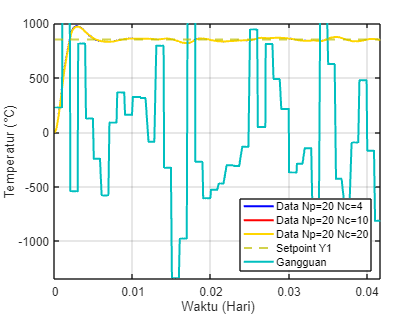

figure(2)
h1 = plot(data_np20nc4_cyc_dist.time,data_np20nc4_cyc_dist.Data(:,1), 'Color','blue', 'LineWidth',2, 'DisplayName',"Data Np=20 Nc=4");
hold on
h2 = plot(data_np20nc10_cyc_dist.time, data_np20nc10_cyc_dist.Data(:,1), 'Color','red', 'LineWidth',2, 'DisplayName',"Data Np=20 Nc=10");
h3 = plot(data_np20nc10_cyc_dist.time, data_np20nc20_cyc_dist.Data(:,1), 'Color',[1, 0.84, 0], 'LineWidth',2, 'DisplayName', "Data Np=20 Nc=20");
h4 = yline(850, '--', 'LineWidth', 2, 'Color', [0.75, 0.75, 0], 'DisplayName', 'Setpoint Y1');
h5 = yline(1450, '--', 'LineWidth', 2, 'Color', [0.85, 0.33, 0.1], 'DisplayName', 'Setpoint Y2');
h6 = plot(data_np20nc4_cyc_dist.time, data_np20nc4_cyc_dist.Data(:,2), 'Color',[0, 0.75, 0.75], 'LineWidth',2, 'DisplayName', "Gangguan");
xlim([data_np10nc4_dist.time(1), data_np10nc4_dist.time(end)])
ylim([min(data_np4nc4_cyc_dist.Data(:, 2)), 1000])
legend([h1, h2, h3, h4, h6], 'Location', 'southeast')

ylabel("Temperatur (°C)")
xlabel("Waktu (Hari)")
grid on
hold off

### **Rotary Kiln Tanpa Gangguan**

**Variasi Np**

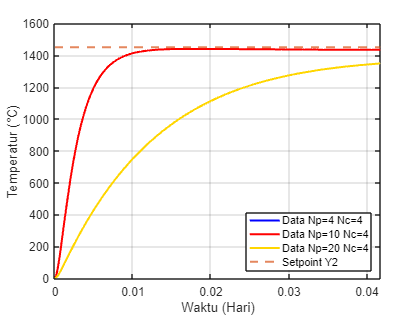

figure(2)
clf;
h1 = plot(data_np10nc4_kiln.time,data_np4nc4_kiln.Data(:,1), 'Color','blue', 'LineWidth',2, 'DisplayName',"Data Np=4 Nc=4");
hold on
h2 = plot(data_np10nc4_kiln.time, data_np10nc4_kiln.Data(:,1), 'Color','red', 'LineWidth',2, 'DisplayName',"Data Np=10 Nc=4");
h3 = plot(data_np10nc4_kiln.time, data_np20nc4_kiln.Data(:,1), 'Color',[1, 0.84, 0], 'LineWidth',2, 'DisplayName', "Data Np=20 Nc=4");
%h4 = yline(850, '--', 'LineWidth', 2, 'Color', [0.75, 0.75, 0], 'DisplayName', 'Setpoint Y1');
h5 = yline(1450, '--', 'LineWidth', 2, 'Color', [0.85, 0.33, 0.1], 'DisplayName', 'Setpoint Y2');
%h6 = plot(data_np10nc4_dist.time, data_np20nc4_dist.Data(:,3), 'Color',[0, 0.75, 0.75], 'LineWidth',2, 'DisplayName', "Gangguan");
xlim([data_np10nc4_dist.time(1), data_np10nc4_dist.time(end)])
ylim([min(data_np4nc4_dist.Data(:, 1)), 1600])
legend([h1, h2, h3, h5], 'Location', 'southeast')

ylabel("Temperatur (°C)")
xlabel("Waktu (Hari)")
grid on
hold off

**Variasi Nc**

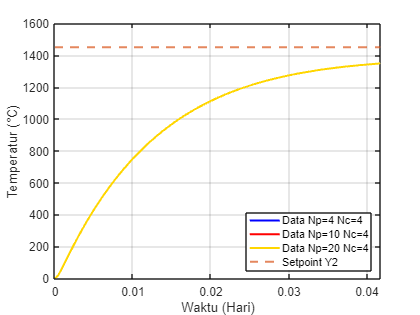

figure(2)
clf
h1 = plot(data_np10nc4_kiln.time,data_np20nc4_kiln.Data(:,1), 'Color','blue', 'LineWidth',2, 'DisplayName',"Data Np=4 Nc=4");
hold on
h2 = plot(data_np10nc4_kiln.time, data_np20nc10_kiln.Data(:,1), 'Color','red', 'LineWidth',2, 'DisplayName',"Data Np=10 Nc=4");
h3 = plot(data_np10nc4_kiln.time, data_np20nc20_kiln.Data(:,1), 'Color',[1, 0.84, 0], 'LineWidth',2, 'DisplayName', "Data Np=20 Nc=4");
%h4 = yline(850, '--', 'LineWidth', 2, 'Color', [0.75, 0.75, 0], 'DisplayName', 'Setpoint Y1');
h5 = yline(1450, '--', 'LineWidth', 2, 'Color', [0.85, 0.33, 0.1], 'DisplayName', 'Setpoint Y2');
%h6 = plot(data_np10nc4_dist.time, data_np20nc4_dist.Data(:,3), 'Color',[0, 0.75, 0.75], 'LineWidth',2, 'DisplayName', "Gangguan");
xlim([data_np10nc4_dist.time(1), data_np10nc4_dist.time(end)])
ylim([min(data_np4nc4_dist.Data(:, 1)), 1600])
legend([h1, h2, h3, h5], 'Location', 'southeast')

ylabel("Temperatur (°C)")
xlabel("Waktu (Hari)")
grid on
hold off

### **Rotary Kiln Dengan Gangguan**

**Variasi Np**

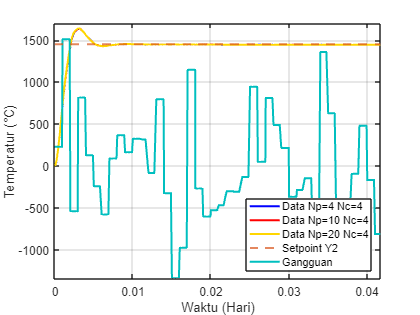

figure(2)
clf
h1 = plot(data_np4nc4_kiln_dist.time,data_np4nc4_kiln_dist.Data(:,1), 'Color','blue', 'LineWidth',2, 'DisplayName',"Data Np=4 Nc=4");
hold on
h2 = plot(data_np10nc4_cyc_dist.time, data_np10nc4_kiln_dist.Data(:,1), 'Color','red', 'LineWidth',2, 'DisplayName',"Data Np=10 Nc=4");
h3 = plot(data_np20nc4_cyc_dist.time, data_np20nc4_kiln_dist.Data(:,1), 'Color',[1, 0.84, 0], 'LineWidth',2, 'DisplayName', "Data Np=20 Nc=4");
%h4 = yline(850, '--', 'LineWidth', 2, 'Color', [0.75, 0.75, 0], 'DisplayName', 'Setpoint Y1');
h5 = yline(1450, '--', 'LineWidth', 2, 'Color', [0.85, 0.33, 0.1], 'DisplayName', 'Setpoint Y2');
h6 = plot(data_np20nc4_cyc_dist.time, data_np20nc4_cyc_dist.Data(:,2), 'Color',[0, 0.75, 0.75], 'LineWidth',2, 'DisplayName', "Gangguan");
xlim([data_np10nc4_dist.time(1), data_np10nc4_dist.time(end)])
ylim([min(data_np4nc4_cyc_dist.Data(:, 2)), 1700])
legend([h1, h2, h3, h5, h6], 'Location', 'southeast')

ylabel("Temperatur (°C)")
xlabel("Waktu (Hari)")
grid on
hold off

**Variasi Nc**

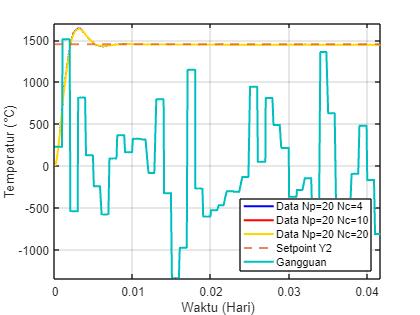

figure(2)
clf
h1 = plot(data_np20nc4_cyc_dist.time,data_np20nc4_kiln_dist.Data(:,1), 'Color','blue', 'LineWidth',2, 'DisplayName',"Data Np=20 Nc=4");
hold on
h2 = plot(data_np20nc10_cyc_dist.time, data_np20nc10_kiln_dist.Data(:,1), 'Color','red', 'LineWidth',2, 'DisplayName',"Data Np=20 Nc=10");
h3 = plot(data_np20nc20_cyc_dist.time, data_np20nc20_kiln_dist.Data(:,1), 'Color',[1, 0.84, 0], 'LineWidth',2, 'DisplayName', "Data Np=20 Nc=20");
%h4 = yline(850, '--', 'LineWidth', 2, 'Color', [0.75, 0.75, 0], 'DisplayName', 'Setpoint Y1');
h5 = yline(1450, '--', 'LineWidth', 2, 'Color', [0.85, 0.33, 0.1], 'DisplayName', 'Setpoint Y2');
h6 = plot(data_np20nc4_cyc_dist.time, data_np20nc4_cyc_dist.Data(:,2), 'Color',[0, 0.75, 0.75], 'LineWidth',2, 'DisplayName', "Gangguan");
xlim([data_np10nc4_dist.time(1), data_np10nc4_dist.time(end)])
ylim([min(data_np4nc4_cyc_dist.Data(:, 2)), 1700])
legend([h1, h2, h3, h5, h6], 'Location', 'southeast')

ylabel("Temperatur (°C)")
xlabel("Waktu (Hari)")
grid on
hold off

## MIMO MPC

[rt, st] = rise_settling_finder(data_np10nc4.Data(:,1), data_np10nc4.time)

rt = 0.0016

st = 0.0040

[rt, st] = rise_settling_finder(data_np10nc4.Data(:,2), data_np10nc4.time)

rt = 0.0134

st = 0.0238


[rt, st] = rise_settling_finder(data_np4nc4.Data(:,1), data_np4nc4.time)

rt = 0.0016

st = 0.0047

[rt, st] = rise_settling_finder(data_np4nc4.Data(:,2), data_np4nc4.time)

rt = 0.0060

st = 0.0098


[rt, st] = rise_settling_finder(data_np20nc4.Data(:,1), data_np20nc4.time)

rt = 0.0016

st = 0.0040

[rt, st] = rise_settling_finder(data_np20nc4.Data(:,2), data_np20nc4.time)

rt = 0.0240

st = 0.0360


[rt, st] = rise_settling_finder(data_np20nc10.Data(:,1), data_np20nc10.time)

rt = 0.0016

st = 0.0024

[rt, st] = rise_settling_finder(data_np20nc10.Data(:,2), data_np20nc10.time)

rt = 0.0240

st = 0.0360


[rt, st] = rise_settling_finder(data_np20nc20.Data(:,1), data_np20nc20.time)

rt = 0.0016

st = 0.0024

[rt, st] = rise_settling_finder(data_np20nc20.Data(:,2), data_np20nc20.time)

rt = 0.0240

st = 0.0360

## with disturbances

[rt, st] = rise_settling_finder(data_np4nc4_dist.Data(:,1), data_np4nc4_dist.time)

rt = 0.0015

st = 0.0020

[rt, st] = rise_settling_finder(data_np10nc4_dist.Data(:,1), data_np4nc4_dist.time)

rt = 0.0015

st = 0.0020

[rt, st] = rise_settling_finder(data_np20nc4_dist.Data(:,1), data_np4nc4_dist.time)

rt = 0.0015

st = 0.0020

[rt, st] = rise_settling_finder(data_np20nc10_dist.Data(:,1), data_np4nc4_dist.time)

rt = 0.0015

st = 0.0020

[rt, st] = rise_settling_finder(data_np20nc20_dist.Data(:,1), data_np4nc4_dist.time)

rt = 0.0015

st = 0.0020


[rt, st] = rise_settling_finder(data_np4nc4_dist.Data(:,2), data_np4nc4_dist.time)

rt = 0.0054

st = 0.0091

[rt, st] = rise_settling_finder(data_np10nc4_dist.Data(:,2), data_np4nc4_dist.time)

rt = 0.0130

st = 0.0215

[rt, st] = rise_settling_finder(data_np20nc4_dist.Data(:,2), data_np4nc4_dist.time)

rt = 0.0216

st = 0.0342

[rt, st] = rise_settling_finder(data_np20nc10_dist.Data(:,2), data_np4nc4_dist.time)

rt = 0.0216

st = 0.0345

[rt, st] = rise_settling_finder(data_np20nc20_dist.Data(:,2), data_np4nc4_dist.time)

rt = 0.0216

st = 0.0345

## SISO MPC

## cyclone

[rt, st] = rise_settling_finder(data_np4nc4_cyc.Data(:,1), data_np4nc4_kiln.time)

rt = 0.0041

st = 0.0070

[rt, st] = rise_settling_finder(data_np10nc4_cyc.Data(:,1), data_np4nc4_kiln.time)

rt = 0.0041

st = 0.0070

[rt, st] = rise_settling_finder(data_np20nc4_cyc.Data(:,1), data_np4nc4_kiln.time)

rt = 0.0108

st = 0.0188

[rt, st] = rise_settling_finder(data_np20nc10_cyc.Data(:,1), data_np4nc4_kiln.time)

rt = 0.0108

st = 0.0188

[rt, st] = rise_settling_finder(data_np20nc20_cyc.Data(:,1), data_np4nc4_kiln.time)

rt = 0.0108

st = 0.0188


[rt, st] = rise_settling_finder(data_np4nc4_kiln.Data(:,1), data_np4nc4_kiln.time)

rt = 0.0058

st = 0.0099

[rt, st] = rise_settling_finder(data_np10nc4_kiln.Data(:,1), data_np4nc4_kiln.time)

rt = 0.0058

st = 0.0099

[rt, st] = rise_settling_finder(data_np20nc4_kiln.Data(:,1), data_np4nc4_kiln.time)

rt = 0.0235

st = 0.0360

[rt, st] = rise_settling_finder(data_np20nc10_kiln.Data(:,1), data_np4nc4_kiln.time)

rt = 0.0235

st = 0.0360

[rt, st] = rise_settling_finder(data_np20nc20_kiln.Data(:,1), data_np4nc4_kiln.time)

rt = 0.0235

st = 0.0360

## with disturbance

[rt, st] = rise_settling_finder(data_np4nc4_cyc_dist.Data(:,1), data_np20nc20_kiln_dist.time)

rt = 0.0013

st = 0.0019

[rt, st] = rise_settling_finder(data_np10nc4_cyc_dist.Data(:,1), data_np20nc20_kiln_dist.time)

rt = 0.0013

st = 0.0019

[rt, st] = rise_settling_finder(data_np20nc4_cyc_dist.Data(:,1), data_np20nc20_kiln_dist.time)

rt = 0.0013

st = 0.0019

[rt, st] = rise_settling_finder(data_np20nc10_cyc_dist.Data(:,1), data_np20nc20_kiln_dist.time)

rt = 0.0013

st = 0.0019

[rt, st] = rise_settling_finder(data_np20nc20_cyc_dist.Data(:,1), data_np20nc20_kiln_dist.time)

rt = 0.0013

st = 0.0019


[rt, st] = rise_settling_finder(data_np4nc4_kiln_dist.Data(:,1), data_np20nc20_kiln_dist.time)

rt = 0.0015

st = 0.0020

[rt, st] = rise_settling_finder(data_np10nc4_kiln_dist.Data(:,1), data_np20nc20_kiln_dist.time)

rt = 0.0015

st = 0.0020

[rt, st] = rise_settling_finder(data_np20nc4_kiln_dist.Data(:,1), data_np20nc20_kiln_dist.time)

rt = 0.0015

st = 0.0020

[rt, st] = rise_settling_finder(data_np20nc10_kiln_dist.Data(:,1), data_np20nc20_kiln_dist.time)

rt = 0.0015

st = 0.0020

[rt, st] = rise_settling_finder(data_np20nc20_kiln_dist.Data(:,1), data_np20nc20_kiln_dist.time)

rt = 0.0015

st = 0.0020

## single test

% MIMO MPC
[rt, st] = rise_settling_finder(data_np12nc4.Data(:,1), data_np12nc4.time)

rt = 0.0013

st = 0.0024

[rt, st] = rise_settling_finder(data_np12nc4.Data(:,2), data_np12nc4.time)

rt = 0.0161

st = 0.0276

% with disturbances
[rt, st] = rise_settling_finder(data_np12nc4_dist.Data(:,1), data_np12nc4_dist.time)

rt = 0.0015

st = 0.0020

[rt, st] = rise_settling_finder(data_np12nc4_dist.Data(:,2), data_np12nc4_dist.time)

rt = 0.0153

st = 0.0259



% SISO MPC
[rt, st] = rise_settling_finder(data_np12nc4_cyc.Data(:,1), data_np12nc4_cyc.time)

rt = 0.0013

st = 0.0019

[rt, st] = rise_settling_finder(data_np12nc4_kiln.Data(:,1), data_np12nc4_kiln.time)

rt = 0.0013

st = 0.0020


[rt, st] = rise_settling_finder(data_np12nc4_cyc_dist.Data(:,1), data_np12nc4_cyc_dist.time)

rt = 0.0013

st = 0.0019

[rt, st] = rise_settling_finder(data_np12nc4_kiln_dist.Data(:,1), data_np12nc4_kiln_dist.time)

rt = 0.0015

st = 0.0020

## additional plot

figure(2)
clf
plot(data_np12nc4_cyc.Time, data_np12nc4_cyc.Data(:,1), 'Color','blue', 'LineWidth', 2, 'DisplayName','Tf cyclone akhir')
hold on;
h4 = yline(850, '--', 'LineWidth', 1.5, 'Color', 'k', 'DisplayName', 'Setpoint')

h4 =   ConstantLine with properties:

    InterceptAxis: 'y'
            Value: 850
            Color: [0 0 0]
        LineStyle: '--'
        LineWidth: 1.5000
            Label: ''
      DisplayName: 'Setpoint'

  Show all properties


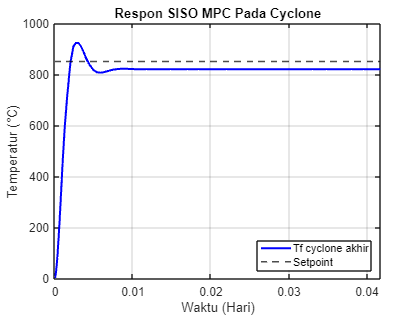

xlim([data_np12nc4_cyc.Time(1), data_np12nc4_cyc.Time(end)])
legend('Location', 'southeast')
title("Respon SISO MPC Pada Cyclone")

ylabel("Temperatur (°C)")
xlabel("Waktu (Hari)")
grid on
hold off


figure(2)
clf
plot(data_np12nc4_kiln.Time, data_np12nc4_kiln.Data(:,1), 'Color','blue', 'LineWidth', 2, 'DisplayName','Tf cyclone akhir')
hold on;
h4 = yline(1450, '--', 'LineWidth', 1.5, 'Color', 'k', 'DisplayName', 'Setpoint')

h4 =   ConstantLine with properties:

    InterceptAxis: 'y'
            Value: 1450
            Color: [0 0 0]
        LineStyle: '--'
        LineWidth: 1.5000
            Label: ''
      DisplayName: 'Setpoint'

  Show all properties


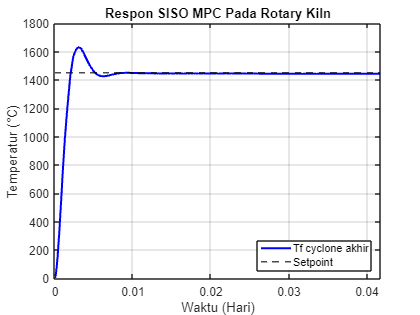

xlim([data_np12nc4_kiln.Time(1), data_np12nc4_kiln.Time(end)])
legend('Location', 'southeast')
title("Respon SISO MPC Pada Rotary Kiln")

ylabel("Temperatur (°C)")
xlabel("Waktu (Hari)")
grid on
hold off